load('C:\Users\Asus\Desktop\data_A')

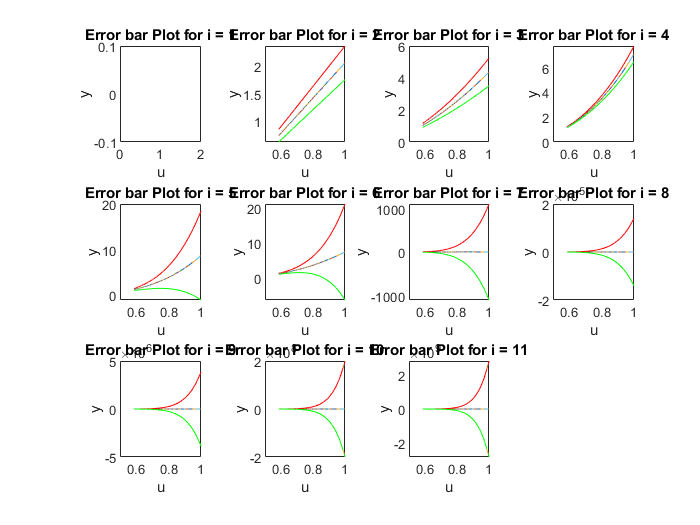

MSE_train=[];
MSE_test=[];
MAE_train=[];
MAE_test=[];
error_test=[];
error_train=[];
all_teta=cell(11, 1);
tetas=[];
ghodrat_noise=[];
deghat_takhmin=[];
deghat_model=[];


%% i dar inja tedade regressor hast, daraje chand jomlei i-1 ast
for i = 1:11
x_train=data_noise(1:500,1:i);
y_train=data_noise(1:500,12);
x_test=data_noise(701:1000,1:i);
y_test=data_noise(701:1000,12); 
   
   
   teta_hat=(x_train'*x_train)^-1*x_train'*y_train;
   all_teta{i} = teta_hat;
   
   y_pred_train=x_train*teta_hat;
   y_pred=x_test*teta_hat;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test(:,i) = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train(:,i) = MSE1;
   
   errors =  y_test - y_pred;
   error_test(:,i)=errors;
   
   errors1 =  y_train - y_pred_train;
   error_train(:,i)=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test(:,i) = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train(:,i) = MAE1;
   
   
subplot_rows = 3;
subplot_cols = 4;

    % Generate the plot for the current i
subplot(subplot_rows, subplot_cols, i);

    if i == 1
       u = x_test(:, 1);
       
    else
       u = x_test(:, 2);

    end
    cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-i);
    errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);

plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
    hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
end
    xlabel('u');
    ylabel('y');
    title(sprintf('Error bar Plot for i = %d', i));

    % Set subplot title

    hold off
    
    
% subplot(subplot_rows, subplot_cols, i);
% u1=1:1:10;
% plot((y_pred(1:10,:)),'-');
% hold on
% plot((y_pred(1:10,:)+errbar(1:10,:)));
% hold on
% plot((y_pred(1:10,:)-errbar(1:10,:)));
% grid
% 
% x=sort(u1).';
% y=sort(y_pred(1:10,:)).';
% data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];
% 
% % Add a box plot
% boxplot(data, 'positions', x, 'widths', 0.5);
% title(sprintf('BoxPlot for i = %d', i));
% hold off



% subplot(subplot_rows, subplot_cols, i);
% plot(y_pred(1:20,:),'.-b','linewidth',2.3);
% hold on
% plot(y_test(1:20,:),'-g','linewidth',2);
% title("y pred & y test");
% legend('y pred', 'y test');
%  hold off 
%  
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;
% % 
% % % Plot 
% % figure
% % plot(sort(y_pred), '--b', 'LineWidth', 2)
% % hold on
% % plot(sort(CI_low), '-.c', 'LineWidth', 1)
% % hold on
% % plot(sort(CI_high), '-.c', 'LineWidth', 1)
% % grid
% % legend('y pred', 'CI_low', 'CI_high')
% % hold off

ghodrat_noise(:,i)=errors.'*errors/(700-i);
deghat_takhmin(:,i)=cov(teta_hat);
deghat_model(:,i)=MSE;




 
end

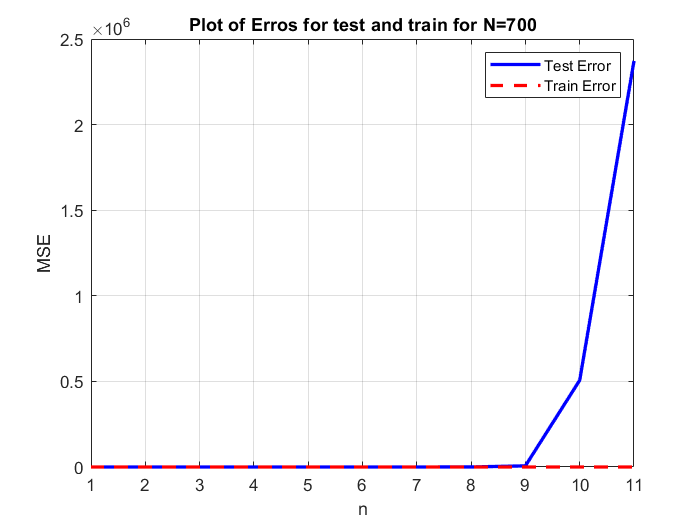



figure;
plot(MSE_test, 'b-', 'LineWidth', 2); 
hold on; % Retain the current plot
plot(MSE_train, 'r--', 'LineWidth', 2); 

% Add labels and legend
xlabel('n');
ylabel('MSE');
title('Plot of Erros for test and train for N=700');
legend('Test Error', 'Train Error');

% Adjust plot appearance if needed
grid on;

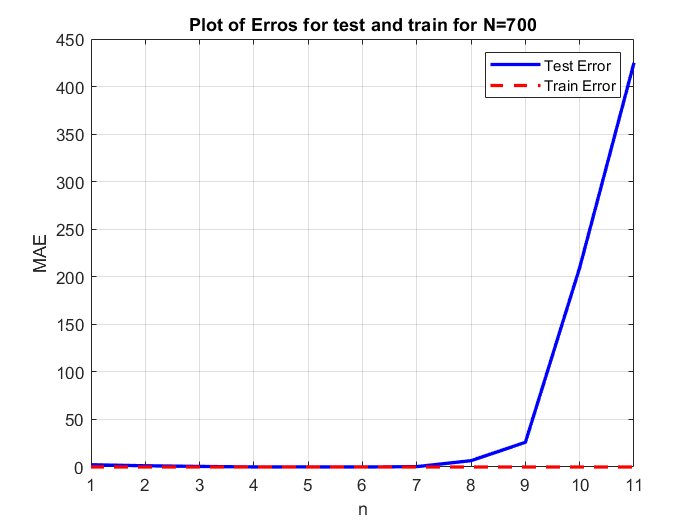


figure;
plot(MAE_test, 'b-', 'LineWidth', 2); 
hold on; % Retain the current plot
plot(MAE_train, 'r--', 'LineWidth', 2); 

% Add labels and legend
xlabel('n');
ylabel('MAE');
title('Plot of Erros for test and train for N=700');
legend('Test Error', 'Train Error');

% Adjust plot appearance if needed
grid on;

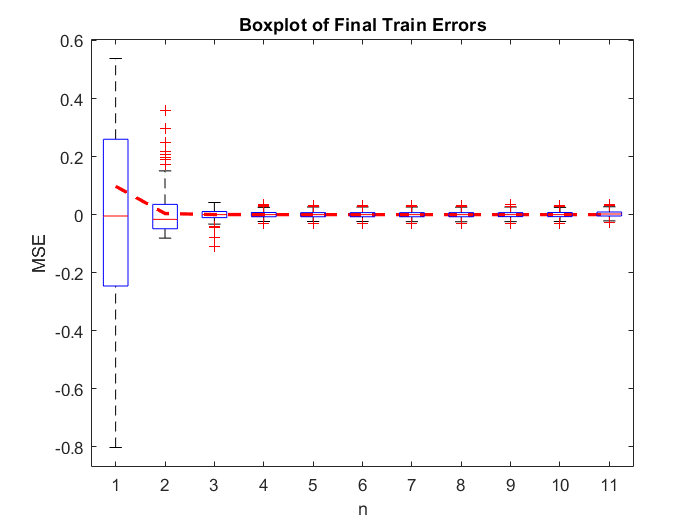


figure;
plot(MSE_train, 'r--', 'LineWidth', 2); 
hold on
% Add a box plot
boxplot(error_train);
title('Boxplot of Final Train Errors');
xlabel('n');
ylabel('MSE');

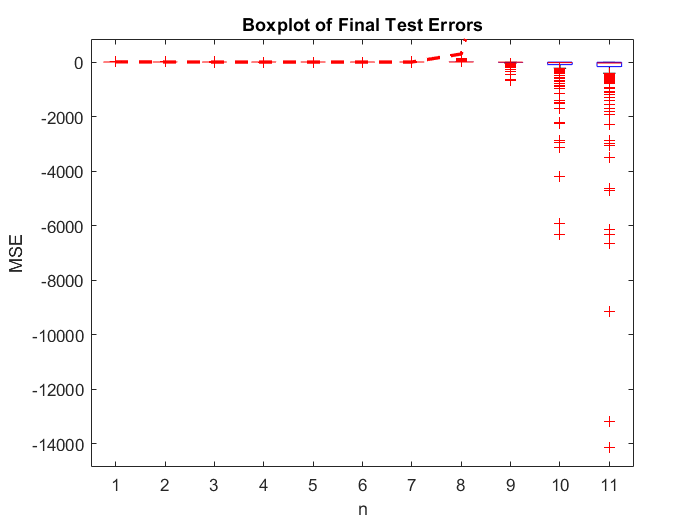

figure;
plot(MSE_test, 'r--', 'LineWidth', 2); 
hold on
% Add a box plot
boxplot(error_test);
title('Boxplot of Final Test Errors');
xlabel('n');
ylabel('MSE');

hold off

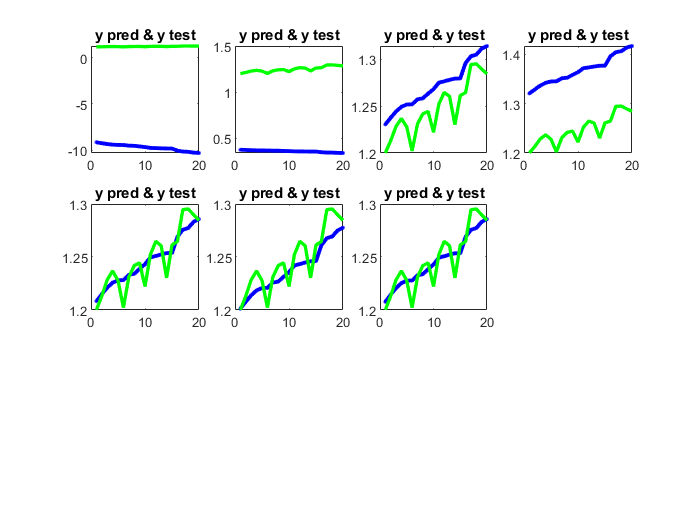


MSE_train=[];
MSE_test=[];
MAE_train=[];
MAE_test=[];
error_test=[];
error_train=[];
all_teta=cell(11, 1);
tetas=[];
ghodrat_noise=[];
deghat_takhmin=[];
deghat_model=[];

p=1;
%% i dar inja tedade regressor hast, daraje chand jomlei i-1 ast
for i = [100,200,300,400,500,600,700]
    
x_train=data_noise(1:i,1:6);
y_train=data_noise(1:i,12);
x_test=data_noise(701:1000,1:6);
y_test=data_noise(701:1000,12); 
   
   
   teta_hat=(x_train'*x_train)^-1*x_train'*y_train;
   all_teta{p} = teta_hat;
   
   y_pred_train=x_train*teta_hat;
   y_pred=x_test*teta_hat;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test(:,p) = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train(:,p) = MSE1;
   
   errors =  y_test - y_pred;
%    error_test(:,p)=errors;
   
   errors1 =  y_train - y_pred_train;
%    error_train(:,p)=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test(:,p) = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train(:,p) = MAE1;
   
   
subplot_rows = 3;
subplot_cols = 4;

    % Generate the plot for the current i
subplot(subplot_rows, subplot_cols, p);

%     if p == 1
%        u = x_test(:, 1);
%        
%     else
       u = x_test(:, 2);
% 
%     end
    cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(length(x_train)-6);
    errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));
% 
%     upper_bound=y_pred + errbar;
%     lower_bound=y_pred - errbar;
%     
%    [a_sorted, sort_idx] = sort(u);
% b_sorted = y_pred(sort_idx);
% c_sorted =upper_bound(sort_idx);
% d_sorted =lower_bound(sort_idx);
% 
% plot(a_sorted, b_sorted, '-');
% hold on;
% plot(a_sorted, c_sorted, '-');
% hold on
% plot(a_sorted, d_sorted, '-');
% hold on
% 
% for j = 1:length(a_sorted)-1
%     x = [a_sorted(j), a_sorted(j+1)];
%     y = [b_sorted(j), b_sorted(j+1)];
%     plot(x, y);
%     hold on
%     xx = [a_sorted(j), a_sorted(j+1)];
%     yy = [c_sorted(j), c_sorted(j+1)];
%     plot(xx, yy, 'r--');
%     hold on
%     xxx = [a_sorted(j), a_sorted(j+1)];
%     yyy = [d_sorted(j), d_sorted(j+1)];
%     plot(xxx, yyy, 'g--');
% end
%     xlabel('u');
%     ylabel('y');
%     title(sprintf('Error bar Plot for i = %d', i));
% 
%     % Set subplot title
% 
     hold off
    
    
% subplot(subplot_rows, subplot_cols, i);
% u1=1:1:10;
% plot((y_pred(1:10,:)),'r-');
% hold on
% plot((y_pred(1:10,:)+errbar(1:10,:)),'g-');
% hold on
% plot((y_pred(1:10,:)-errbar(1:10,:)),'b-');
% grid
% % 
% x=sort(u1).';
% y=sort(y_pred(1:10,:)).';
% data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];
% 
% % Add a box plot
% boxplot(data, 'positions', x, 'widths', 0.5);
% title(sprintf('BoxPlot for i = %d', i));
% hold off



plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 
 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
%     upper_bound=y_pred + errbar;
%     lower_bound=y_pred - errbar;
%     
%    [a_sorted, sort_idx] = sort(u);
% b_sorted = y_pred(sort_idx);
% c_sorted =upper_bound(sort_idx);
% d_sorted =lower_bound(sort_idx);
% 
% plot(a_sorted, b_sorted, '-');
% hold on;
% plot(a_sorted, c_sorted, '-');
% hold on
% plot(a_sorted, d_sorted, '-');
% hold on
% 
% for j = 1:length(a_sorted)-1
%     x = [a_sorted(j), a_sorted(j+1)];
%     y = [b_sorted(j), b_sorted(j+1)];
%     plot(x, y);
%     hold on
%     xx = [a_sorted(j), a_sorted(j+1)];
%     yy = [c_sorted(j), c_sorted(j+1)];
%     plot(xx, yy, 'r--');
%     hold on
%     xxx = [a_sorted(j), a_sorted(j+1)];
%     yyy = [d_sorted(j), d_sorted(j+1)];
%     plot(xxx, yyy, 'g--');
% end
%     xlabel('u');
%     ylabel('y');
%     title(sprintf('Error bar Plot for i = %d', i));
% 
%     % Set subplot title

    hold off
    
    
% u1=1:1:20;
% plot((y_pred(1:20,:)),'-');
% hold on
% plot((y_pred(1:20,:)+errbar(1:20,:)));
% hold on
% plot((y_pred(1:20,:)-errbar(1:20,:)));
% grid
% 
% x=sort(u1).';
% y=sort(y_pred(1:20,:)).';
% data = [((y_pred(1:20,:))-errbar(1:20,:)).'; (y_pred(1:20,:)).'; ((y_pred(1:20,:))+errbar(1:20,:)).'];
% 
% % Add a box plot
% boxplot(data, 'positions', x, 'widths', 0.5);
% title(sprintf('BoxPlot for i = %d', i));
% hold off


 

ghodrat_noise(:,p)=errors.'*errors/(length (x_train)-6);
deghat_takhmin(:,p)=cov(teta_hat);
deghat_model(:,p)=MSE;

 p=p+1;


 
end

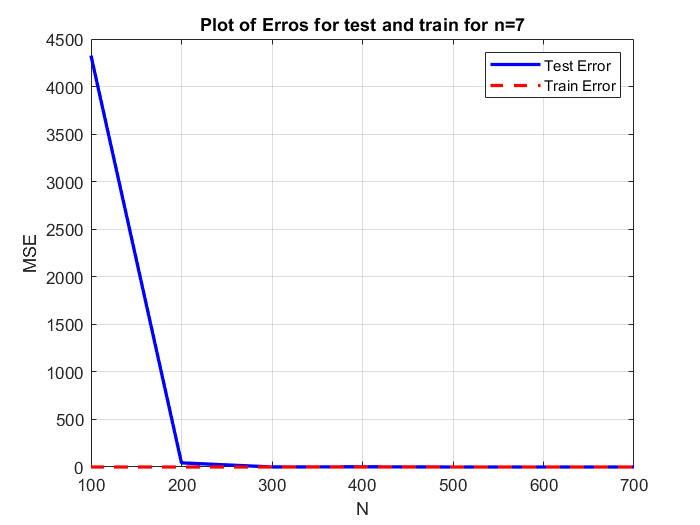

N=[100,200,300,400,500,600,700];
figure;
plot(N,MSE_test, 'b-', 'LineWidth', 2); 
hold on; % Retain the current plot
plot(N,MSE_train, 'r--', 'LineWidth', 2); 

% Add labels and legend
xlabel('N');
ylabel('MSE');
title('Plot of Erros for test and train for n=7');
legend('Test Error', 'Train Error');

% Adjust plot appearance if needed
grid on;

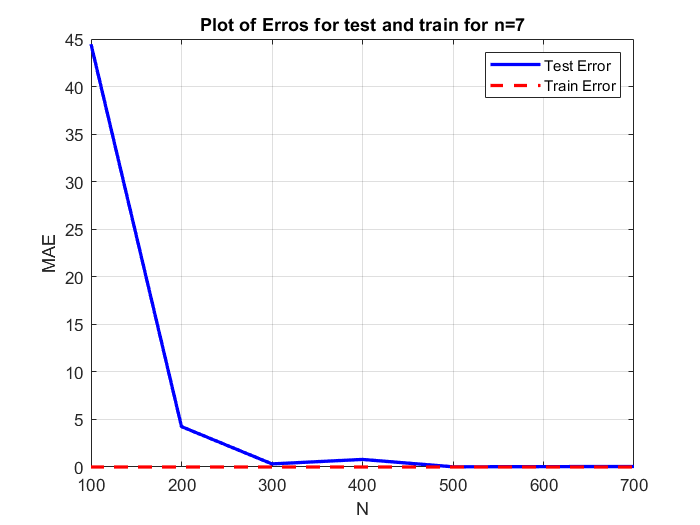

N=[100,200,300,400,500,600,700];
figure;
plot(N,MAE_test, 'b-', 'LineWidth', 2); 
hold on; % Retain the current plot
plot(N,MAE_train, 'r--', 'LineWidth', 2); 

% Add labels and legend
xlabel('N');
ylabel('MAE');
title('Plot of Erros for test and train for n=7');
legend('Test Error', 'Train Error');

% Adjust plot appearance if needed
grid on;